# Ejercicios raíces

## Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\mathrm{tanh}\left(\sqrt{g\frac{c_d }{m}}\right)t$$


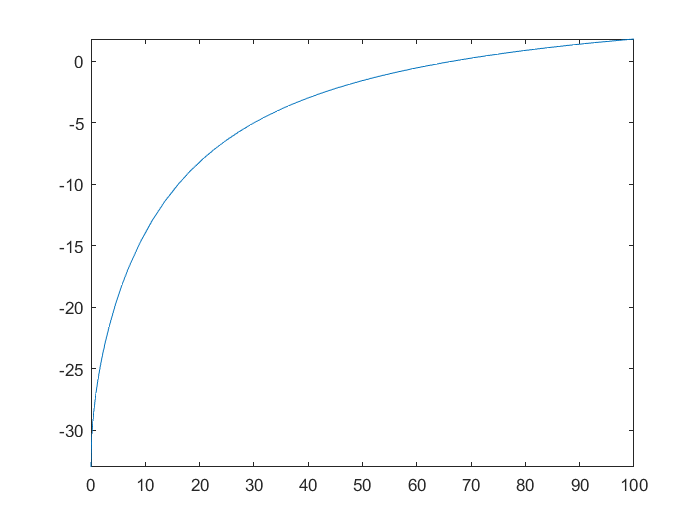

g = 9.81;
cd = 0.25;
t = 4;
vMax = 33; % ¿cómo sé cuándo tengo que agregar los puntos?
f=@(m) (sqrt(g*m./cd).*tanh(t*sqrt(g*cd./m)))-vMax;
fplot(f,[0,100])

biseccion(f,35,100)

ans = 66.6000

## Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la **fuerza de flotación** es igual al **peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu 0álculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante

 
$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


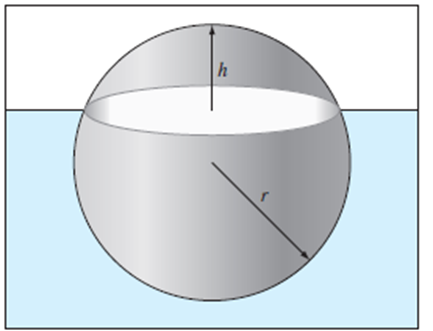

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

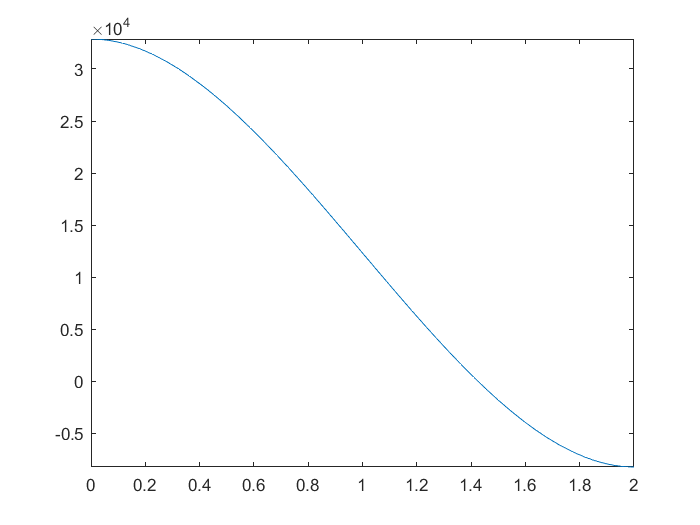

g = 9.81;
pe = 200;
pa = 1000;
r = 1;
vol_total = (4/3)*pi*r^3;
vol_arriba = @(h) (pi/3)*(h.^2).*(3*r-h);
m = vol_total*pe;
F = m*g;


ftotal = @(h) (vol_total-vol_arriba(h))*g*pa - F;
fplot(ftotal,[0,2*r]); % la hmax es 2 veces el radio

biseccion(ftotal,0,2*r);

ans = 1.4257

## Funciones del script


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\mathrm{tanh}\left(\sqrt{g\frac{c_d }{m}}\right)t$$
